# 2. Voltage and Current Sources

© B. Rasnow 31May25

## Objectives

We'll explore how voltage, current, power, and resistance are related by modeling a simple series circuit in MATLAB. We'll show why a voltage source in series with a large resistor acts like a current source, and how "loading" a circuit (taking power from it) changes its characteristics. 

## What are voltage and current? 

I live on a ranch and thus fix a lot of plumbing problems. No water at my sink or shower, I have to diagnose and fix the problem myself. So for me, analogies between water and electricity [1] are more real and intuitive than perhaps for you, and you may have to discover other analogies to help you correctly predict and understand  electrical phenomena. In the water analogy, charge is analogous to mass, flow is current, and pressure is analogous to voltage. 1 Coulomb is the standard unit of charge = –6.24e18 electrons -- so much for analogies!

Think about your kitchen sink for a moment. Behind the faucet is pressure -- we know that is true because when the faucet is opened, water flows. Pressure is analogous to voltage, which can be defined as "the ability to move charge through a finite resistance". The faucet is an infinite resistance when closed, hence no flow (unless it leaks, i.e., it has finite resistance). Current is analogous to flow. 1 Ampere = the movement of 1 Coulomb of charge per second past any given point. Charge generally doesn't accumulate, so the flow into one end of a wire = the flow everywhere in the wire = the flow out the other end. Power = voltage * current = the rate of energy flow. In standard units, 1 Watt = 1 Volt * 1 Ampere = 1 Joule/Coulomb * 1 Coulomb/second = 1 Joule/second. Resistance is analogous to friction, something that opposes flow and converts flow energy into heat. 

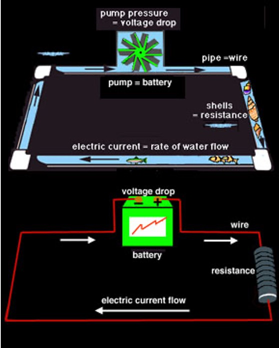

        Figure 1. Analogies between water systems and electrical systems can be useful: pressure, flow, obstruction are analogous to voltage, current, and resistance.

Another example of the relationships between pressure, current, and resistance, is seen when you put your finger over the end of a garden hose. As the resistance from your finger's constriction increases, the flow decreases, but the stream of water shoots further and higher. What's going on? The kinetic energy, $\frac{1}{2}{\textrm{mv}}^{2\;} ,$ of the water leaving the hose decreases as it converts to gravitational potential energy ($mgh$), so pinching off and reducing the flow increases the water's initial velocity, and hence its initial pressure. So how does the pressure at the end of a hose inversely relate to the flow? Well, Ohm's law of course! The pressure originates far away, at a pump or water tank. For simplicity, imagine the water pressure originates from a water tank on a hill or tower above, providing constant pressure $\rho g h$, that would be indicated by a pressure gauge attached to the hose. When the hose faucet is opened and flow begins, the same pressure gauge would indicate a drop in pressure, due to friction in the water lines and hose. The more flow, the more friction loss, the less pressure at the end of the hose. The electrical analogy is an ideal battery at the tank, with voltage Vo = $\rho g h$. The pressure gauge is analogous to a voltmeter, and would read Vo at the end of the hose when there is no current. Where the analogy gets mucky is that opening the hose faucet is analogous to *closing* or shorting the circuit (because electric current always flows in loops). The current (flow) is now limited by friction, the "parasitic" or internal series resistance of the pipes and hose, and the pressure at the open end of the hose drops to V =  Vo - i*Rseries by Ohm's Law. 

Apologies if that only confused you more -- if so and if its a hot day like it is as I write this, go outside and cool off with a hose, and see if you make intuitive sense of how pressure, flow, and resistance are related. 

Concluding this section, its not easy to construct an intuitive sense of the relationships between voltage, current, resistance, power, time, etc., largely because we don't have innate experience with this physics. The analogy between water and electricity isn't perfect. For example, water flows when a valve is opened, but electric (direct) current only flows when the circuit (pipes) are closed ...(alternating current behaves differently). Electricity does what it does and our task is to describe and predict its behavior. We can do that with physical laws like Maxwell's Equations (which are accurate but very unwieldy to use), with imperfect analogies, and algebraic rules like Kirchhoff's and Ohm's Laws. The later can be summarized as follows: voltage is related to potential energy, like the fuel in a car (containing chemical potential energy). Without voltage, charges won't move (except for tiny random thermal jiggling called [Johnson-Nyquist Noise](https://en.wikipedia.org/wiki/Johnson%E2%80%93Nyquist_noise)). When two points are separated by a voltage $V$and a finite resistance $R$, then charges will flow through the $R$ at a rate $I = \frac{dQ}{dt} = V/R$. That's not a complete story, but it will enable us to explore stationary currents in circuits. 

This is our common intellectual toolbox and language to describe the physics of electricity. It is essential that you use the terminology accurately and consistently, or else we'll have no idea what we're talking about. It will take effort and time, memorization and practice, to become savvy with this language. The alternative is ignorance and chaos. 

## What is MATLAB? 

Here's how the company behind it summarizes it: [https://www.youtube.com/watch?v=joilU9m-sNk](https://www.youtube.com/watch?v=joilU9m-sNk) and I won't try to do better. Why am I introducing MATLAB here and now, front and center? Isn't it hard enough to learn electronics without muddying the water with learning a complex computer programming environment at the same time? In my prior career as a Principal Scientist in a biotechnology company, I taught co-workers MATLAB calling it "Excel on Steroids". Numerical data plays an enormous role helping us explore and understand electronics. Think about it, we can't explore (low voltage) electricity by "feeling" it. Any intuition we develop will be constructed from instrumental measurments, data reduction, and visualization -- the things that MATLAB does best. In this course, MATLAB is essential gear in the same way boots, ice ax, and ropes are essential gear for high altitude climbers. With practice you'll learn to wield these tools -- and the good news is mistakes are unlikely to be as painful or fatal. 

Why not use a different programming language (e.g., Python)? An old saying goes "**In theory, there is no difference between theory and practice; but in practice, there is.**" Each programming language offers particular strengths and liabilities. I've chosen MATLAB for this course because I believe it offers

-  By far the simplest, most compact [syntax](https://en.wikipedia.org/wiki/Syntax) and [semantics](https://en.wikipedia.org/wiki/Semantics) for expressing the ideas we're exploring. The MATLAB code we'll be running would be much longer, more verbose, and thus prone to errors, when written in other languages. Such conciseness saves us time and lets us focus more on the application (electronics) than the programming and implementation.

- MATLAB's language and environment (IDE) are robust, stable, and well supported. 

- Although commercially expensive, MATLAB *is* widely available since many universities and large companies have site licenses. It's cost is justified (amortized) in the time saved compared to coding in other environments.

- There is a free public domain version ([https://octave.org](https://octave.org)) that we could use with minor changes to our code. But it tends to lag behind MATLAB in features (and support), so since we have a site license for MATLAB, we'll use it.

There is nothing in this course that can't be done (in theory) with Python or C, or many other programming languages. But one would have to be an experienced programmer (with much more time to spare) to write and debug code that acheives comparable results to our handful of MATLAB commands. It takes a lot of effort, time, memorization and practice, to become savvy with any (programming) language, and your exposure to MATLAB (and C) in this course will start you on that journey.

## Modeling an ideal voltage source and series resistor

Consider this simple series circuit with an ideal voltage source Vth ("ideal" means the votlage is constant, independent of the current) and an ideal (constant) series resistance Rth, in series with an external Rs. What will be the voltage across and current through Rs, as Rs is varied? Before answering that, you may be wondering what the "th" stands for. Léon Charles Thévenin came up with a powerful theorem in 1883, [https://en.wikipedia.org/wiki/Léon_Charles_Thévenin](https://en.wikipedia.org/wiki/L%C3%A9on_Charles_Th%C3%A9venin) [2] that's still relevant to modern circuit theory! 

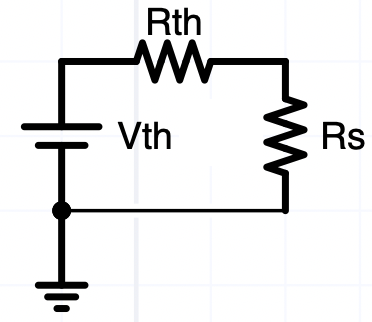

        Figure 2. Simple circuit we'll model: an ideal voltage source in series with two resistors.

To simulate this circuit, we'll assign numerical values to the parameters -- below are some initial guesses, which are easy enough to change if we think there maybe interesting behaviors that we're missing in other regions of "parameter space". How are the voltages and currents of interest related to these parameters? Rth and Rs are in series, so the ubiquitous voltage divider equation ([https://en.wikipedia.org/wiki/Voltage_divider](https://en.wikipedia.org/wiki/Voltage_divider)) [3] gives the voltage across $R_S$ as $V_S = V_{th} \frac{R_S}{R_S+R_{th}}$ and Ohm's Law gives $i_S = V_s/R_S = V_{th}/(R_s+R_{th})
$. To express as executable MATLAB code, assign numerical values to the parameters and compute the variables. We can assign single ("scalar") values or a range of discrete values ("vectors") with the functions `linspace` or `logspace`. Invoke MATLAB's `>> help logspace` or `>> doc logspace` help functions to learn more about them. 

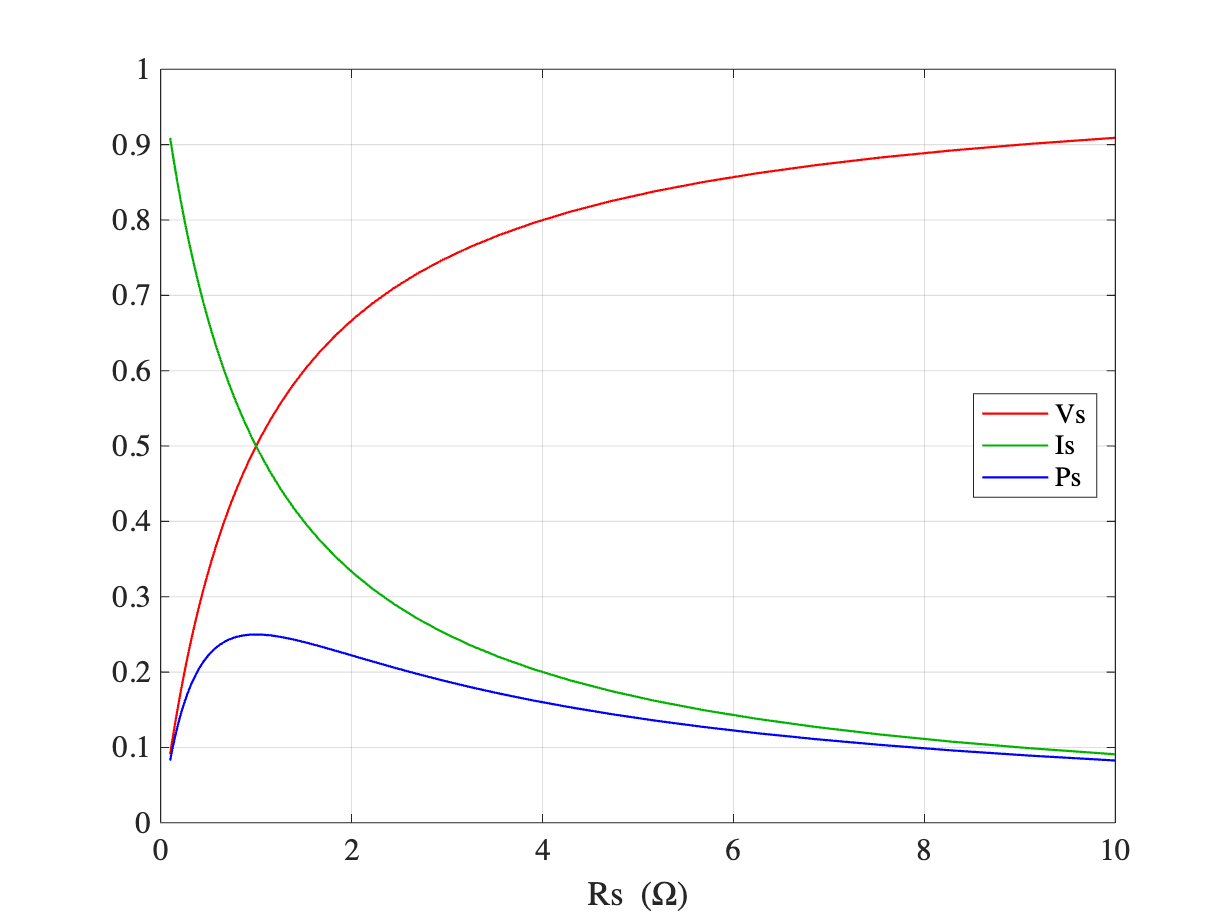

Vth = 1; % volts
Rth = 1; % ohms
Rs = logspace(-1,1)'; % a range of values as column vector
Vs = Vth * Rs ./ (Rs+Rth); % point-wise division since Rs is a vector
Is = Vs ./ Rs; % Ohm's Law
Ps = Vs .* Is; % Watt's Law
plot(Rs, [Vs Is Ps]); 
xlabel('Rs (\Omega)'); grid;
legend('Vs','Is','Ps','location','best');

  Figure 3. Voltage, current, and power as Rs varies between 0.1-10$\Omega$.

Voltage is in volts, current in amps, and power in watts. What does this tell us -- what conclusions should we take away? When results surprise us, it means either 1) they're wrong because we messed up, 2) our intuition is wrong and we need to rewire our brain, or 3) both 1) and 2). A good way to test results like these is to reason out their asymptotic behaviors. Start with what's happening on the left side where Rs << Rth. The current is big because the total resistance = Rs+Rth ~ Rth is minimum. Quantitatively, current i = 1V/1.1ohms = 0.9A (check). Vs is given by Ohm's Law, Vs = 0.9A * 0.1Ohms = .09V is tiny as shown (check). P = V*I = .09V*.9A=.08W as shown (within 1 significant figure). So no reason to doubt that side of the graph, what about the right side? Rs >> Rth --> Rtotal ~ Rs = 10 ohms, or more precisely, 11 ohms. The current approaches  i = 1V/11 ohms ~ 0.1amps as shown, and V = IR --> 0.1amps * 10 ohms = 1V. Power ~ VI ~ 1V * .1A = .1W as shown. What are the chances we got these two ends of the curves right, but the middle is all wrong? Hopefully you doubt that -- in science we generally don't prove ideas are true. Rather, our confidence increases the more we test our theories and they pass those tests, as this model has has passed its asymptotic tests. If you were expecting different behaviors from such a simple 2 resistor circuit, then you should be questioning why your intuition was wrong, and what other  misconceived notions might need to be purged from your brain. Many students of electronics are challenged or give up because they refuse to reject their incorrect preconceptions. 

The symmetry of this system and its asymptotic behaviors are more apparent with a wider range of Rs displayed on a semilog axis: 

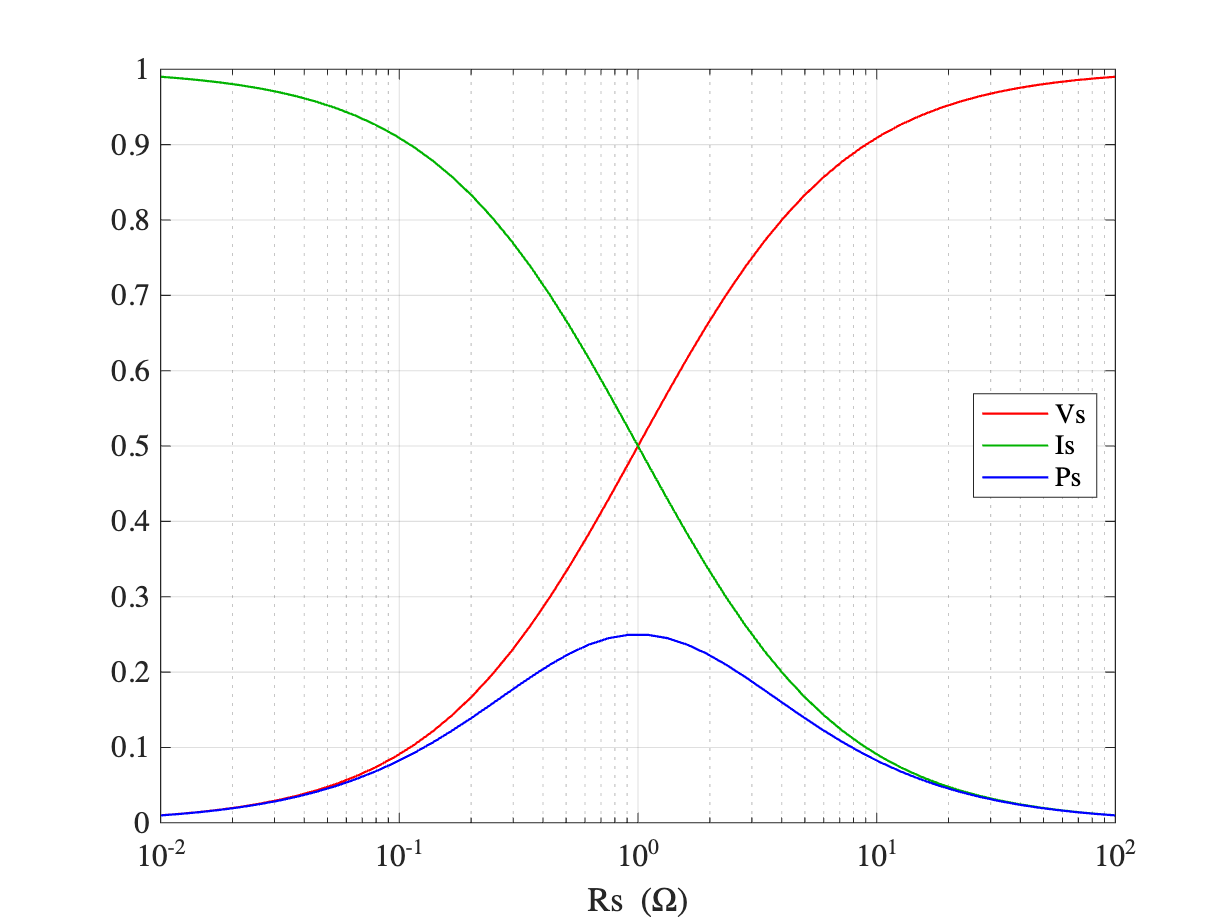

Rs = logspace(-2, 2)'; % a range of values
Vs = Vth * Rs ./ (Rs+Rth); % point-wise division since Rs is a vector
Is = Vs ./ Rs; 
Ps = Vs .* Is;
semilogx(Rs, [Vs Is Ps]); 
xlabel('Rs (\Omega)'); grid;
legend('Vs','Is','Ps','location','best');

       Figure 4. Voltage, current, and power as Rs varies between 0.01-100$\Omega$, on a semilog scale.

Voltages and currents appear as anti-symmetrical sigmoids while the power looks qualitatively Gaussian ... more surprises from this simplest of circuits!? Let's make the y-scale logarithmic too, and further widen the range of Rs: 

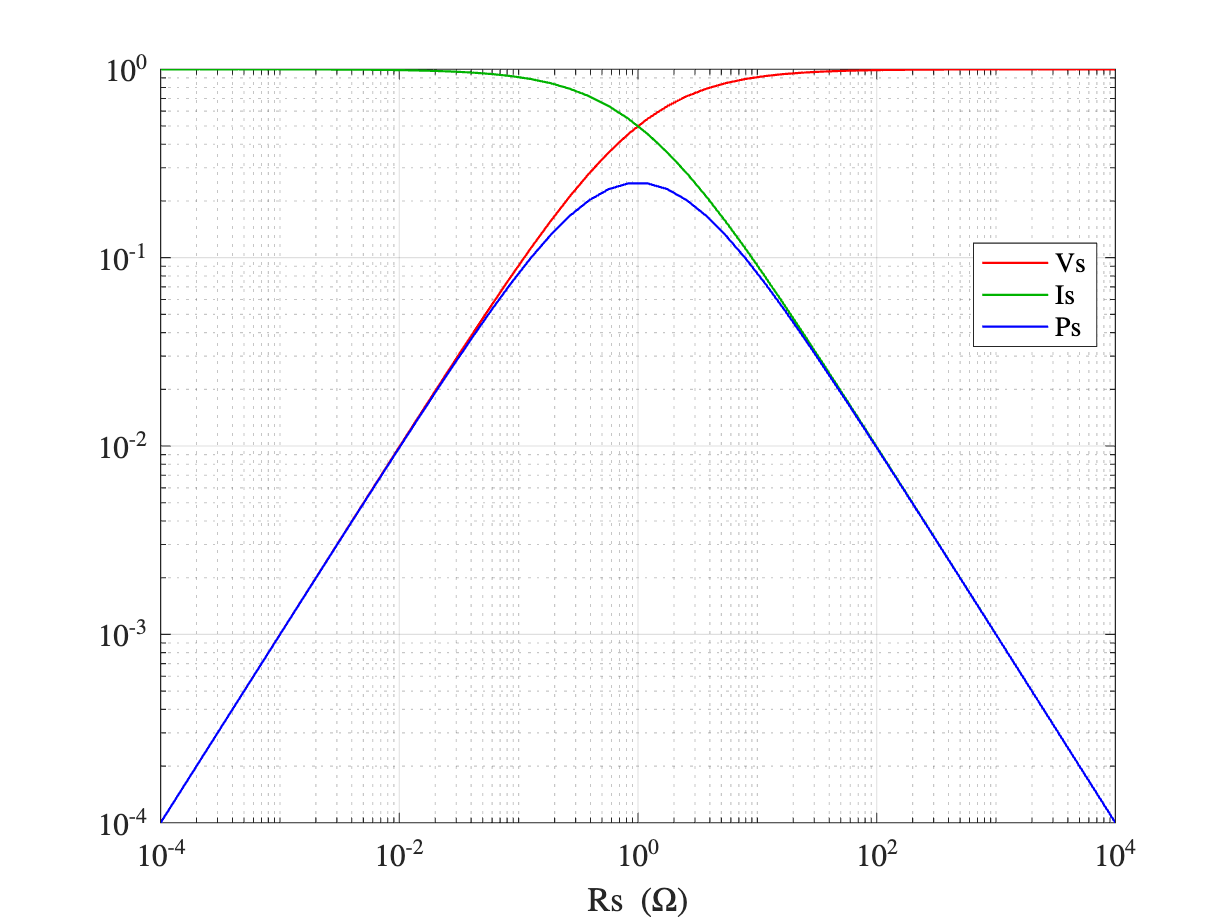

Rs = logspace(-4, 4)'; % a range of values
Vs = Vth * Rs ./ (Rs+Rth); % point-wise division since Rs is a vector
Is = Vs ./ Rs;
Ps = Vs .* Is;
loglog(Rs, [Vs Is Ps]); 
xlabel('Rs (\Omega)'); grid;
legend('Vs','Is','Ps','location','best'); 

        Fig. 5. Voltage, current, and power as Rs varies between 0.0001-10K$\Omega$, shown on a log-log scale.

The sigmoids became simpler linear asymptotes -- just by changing the plot from linear to log, not by changing the data or the model. 

## Discussion

When you look at Fig. 2, what do you *see*? A series circuit, with 3 components -- an ideal voltage source and 2 resistors? Or 2 components: a Thevenin voltage source (Vth *together* with Rth) in series with a second "load resistor" Rs? Or how about seeing it as one, a voltage divider circuit? What's the difference? Only in our heads. As we construct and contemplate more complicated circuits, our brains are limited to hold attention on just a few concepts at once. If we learn how to see related components as abstract single entities, we can manage complexity better. 

Also if you want to simplify Fig. 2, your likely response might be to replace the two resistors with a single one equal to their sum. Although *algebraically* simpler, this would muddle functional and physical boundaries if Rth represents net internal resistance *inside* the power supply, and Rs is a physical "load" connected to the power supply. So functionally, a simplified Fig. 2 would be "a power supply (with finite internal resistance Rth) in series with Rs", or even simpler, a functional description of simply "a voltage divider" that generated Figs. 3-5. 

I called the second resistor "Rs" as a shorter label for "Rseries" -- a resistor in series with the power supply (Vth + Rth), but perhaps better nomenclature would be "RLoad". In electronics, a "load" is "a device that consumes electrical power" ([https://en.wikipedia.org/wiki/Electrical_load](https://en.wikipedia.org/wiki/Electrical_load)). Standard nomenclature can be confusing, for example, a small *value* of Rs or RL is called a "large" or sometimes "heavy" load, and likewise a large *value* of Rs = RL is a small or "weak" load -- because the "load" is proportional to conductance, g = 1/R, but we tend to use R instead of g in electronics. Want more confusion -- isn't Rs *both* in series and in parallel with the power supply (Vth + Rth). 

In Fig. 5 the asymptotic behaviors are apparent. On the left side, Rs << Rth. For small *values* of the load resistance, Rs, current through the load resistance Rs is constant, $i \rightarrow$ Vth / Rth, (as long as Rs << Rth). We can characterize this regime as an ideal "constant current source". The voltage across the load Rs, and the power delivered to the load are both small in this regime. On the right side of Fig. 5, the voltage across the load Rs approaches a constant, Vs $\rightarrow$ Vth independent of Rs (as long as Rs >> Rth). We can thus characterize this regime as a "constant voltage source". However the current is small, as is the power delivered to the load. Asymptotic current and voltage either are constant or fall off with a power law -- e.g., a change of 10 in Rs changes Vs, Is, and Ps by 10. 

What about the middle? When source and load resistances are the same, Rth = Rs, this regime is called "impedance matched" [5]. The voltage and current are each 1/2 of their maximum asymptotic values, but maximum power is transferred from source to load. Half the power is delivered to the source's resistance Rth, and half the circuit's power is delivered to the load resistance Rs. Can you ever deliver more than half? Let's revisit the algebra. The power delivered to Rs is $P_{Load} = V_s * i_s$ where $V_S = V_{th} \frac{R_S}{R_S+R_{th}}$ by the voltage divider equation, and $i_s = i = \frac{V_{th}}{R_s+R_{th}}$, thus $P_{Load} = V_{th}^2 * \frac{R_s}{(R_s+R_{th})^2}$. The power curve in Fig. 5 (blue) represents the fact that $\frac{\partial P_{Load}}{\partial R_s} = 0$ when $R_s = R_{th}$, and $P_{Load} = \frac{V_{th}^2}{4R}$. But *if* we can make $R_{th} \rightarrow 0$, then all (4 times) the power will be delivered to $R_s$. This is a reason superconductors (materials with $R_{th} = 0$) are so desirable for power transfer applications, but this exotic quantum form of matter is not easy to produce and sustain. 

## Reflection and Meta-reflection

The following are general results:

- A voltage source with series Rth >> $R_{load}$ acts like a constant current source (left side of graphs, $I_{Load}$ ~ constant). 

- A voltage source with series Rth << $R_{load}$ acts like a constant voltage source (right side of graphs, $V_{Load}$  ~ constant).

- Maximum power is transferred to a load $R_{load}$ when $R_{load}$ = Rth, and that maximum is just 50% of the power put out by the (ideal) source Vth, the other half is dissapated by Rth. This condition is called "impedance matched", and plays an important role in high frequency transmissions. 

- Plotting data on linear and semi-logaritmic axes can clarify or obfuscate (hide) symmetries in the data. 

- What makes a resistance "large" or "small" is relative to other resistances in the same circuit. A 100$\Omega$ resistor is "small" when in series with 100k$\Omega$, but is "large", i.e., dominates a circuit, that has other series resistances << 100$\Omega$. 

If you learned new relationships between voltage, current, power and resistance in this simplest of circuits, then fasten your seatbelts, for our exploration of electrical circuits is just beginning. I also hope you appreciate the power of numerical modeling and MATLAB as a general tool for exploring physics and engineering equations. We'll be doing lots of similar modeling throughout the course to gain insights into electronic behaviors. Varying resistances over 6 orders of magnitude with high precision is harder experimentally than the way we did it by tweaking parameters in `logspace`. Simulation in MATLAB gives us a powerful ability to explore theory and its consequences with relatively low programming effort (it becomes easier with practice). It let us reframe the voltage divider equation from an algebraic abstraction into a visual/geometrical representation. Being able to see things from radically different perspectives lets us apply them in radically different ways, this is sometimes referred to as "lateral thinking" [7]. 

Another reflection is that what you see and read above is a small fraction of the code I tried on MATLAB's command line in the act of preparing this chapter. Active learning gave me new and deeper understand and you too should be exploring more than is written here. Try variations, different parameters, plot additional relationships. Ask questions of MATLAB and learn how to answer your questions through inquiry. Query `>> help ...` or `>> doc ... `to learn more about MATLAB functions and click through additional hyperlinks in the help system. If you're new to MATLAB, in the command window on the HOME tab, in the RESOURCES block click on the "Learn MATLAB" button, and explore other sources. I strongly recommend this book by Attaway, "MATLAB[: A Practical Introduction to Programming and Problem Solving](https://www.amazon.com/MATLAB-Practical-Introduction-Programming-Problem/dp/0128154799)", any recent edition. It presents general programming concepts and their expression in MATLAB. 

## Further exploration

- We've plotted data using `plot`, `semilogx`, and `loglog`. MATLAB offers other ways to tweak the axes without replotting. There are GUI tools to do that, or use the `set` command, e.g., `set(gca,'xscale','linear');` or `set(gca,'yscale','log')`. `help gca` explains some of these commands, `get(gca)` shows all the fields and values of a plot. `set` and `get` are powerful interface functions to access graphics (and other) objects in MATLAB. Yet another method to manuipulate these graphical object properties is: `ax = gca; ax.XScale = 'log'; T`here are also GUI interfaces to graphic objects -- can you find them?

- What analogies help you understand voltage and current? How do they help, and where do they break down? 

- What surprised you the most about this activity? How can you reformulate your intuition so as to not be surprised again by these truths?

- If you know calculus, prove that power is maximum when `Rs = Rth`, by solving $\frac{\partial P}{\partial R_s} = 0$.

## References

[1] [https://en.wikipedia.org/wiki/Hydraulic_analogy](https://en.wikipedia.org/wiki/Hydraulic_analogy)

[2] Thevenin's theorem:[https://en.wikipedia.org/wiki/Thévenin%27s_theorem](https://en.wikipedia.org/wiki/Th%C3%A9venin%27s_theorem)

[3] [https://en.wikipedia.org/wiki/Voltage_divider](https://en.wikipedia.org/wiki/Voltage_divider)

[4] [https://en.wikipedia.org/wiki/Electrical_load](https://en.wikipedia.org/wiki/Electrical_load)

[5] [https://en.wikipedia.org/wiki/Impedance_matching](https://en.wikipedia.org/wiki/Impedance_matching)

[6] Attaway, "MATLAB[: A Practical Introduction to Programming and Problem Solving](https://www.amazon.com/MATLAB-Practical-Introduction-Programming-Problem/dp/0128154799)"

[7] [https://en.wikipedia.org/wiki/Lateral_thinking](https://en.wikipedia.org/wiki/Lateral_thinking) 